B3_1 cosine signal

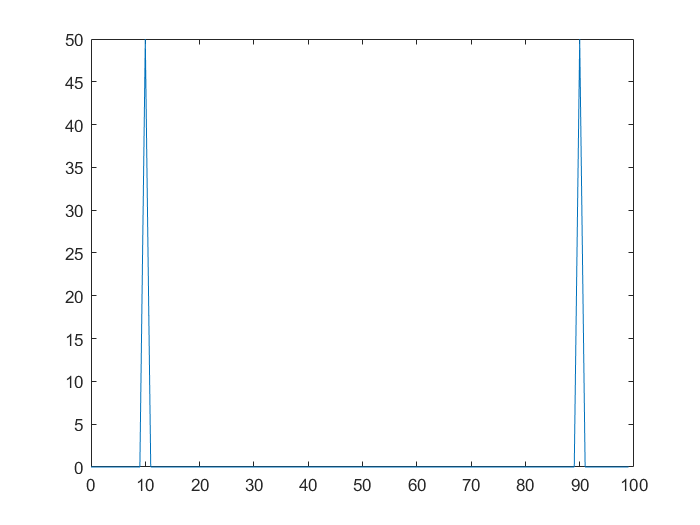

clear
Fs = 100; % Sampling frequency
T = 1/Fs; % Sampling period
t = 0:T:1-T; % Time vector
y3 = cos(2*pi*10*t+pi/5); % omgea = 5
Y3 = fft(y3);
f3 = (0:length(Y3)-1)*Fs/length(Y3);
plot(f3,abs(Y3))

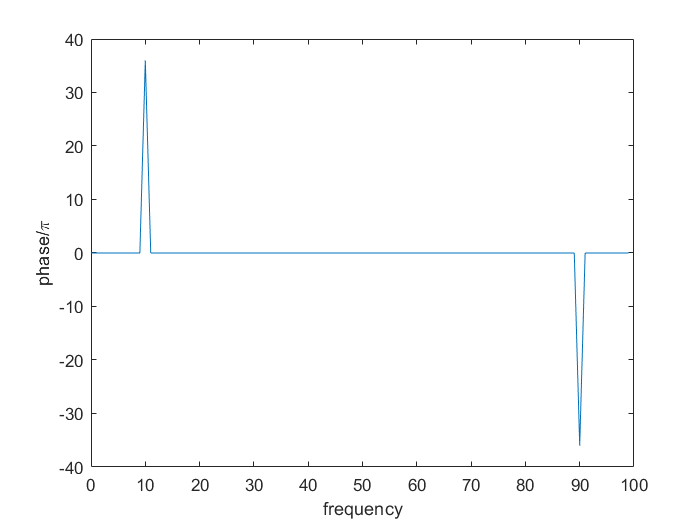

% Z3 = fftshift(Y3);
% f3 = (-length(Y3)/2:length(Y3)/2-1)*Fs/length(Y3);
% plot(f3,abs(Z3))
% xlabel('frequency')
% ylabel('amplitude')
Z3 = Y3;
tol = 1e-6;
Z3(abs(Z3)<tol)=0;
theta3 = angle(Z3);
plot(f3,theta3*180/pi)
xlabel('frequency')
ylabel('phase/\pi')

B3_2  A step signal

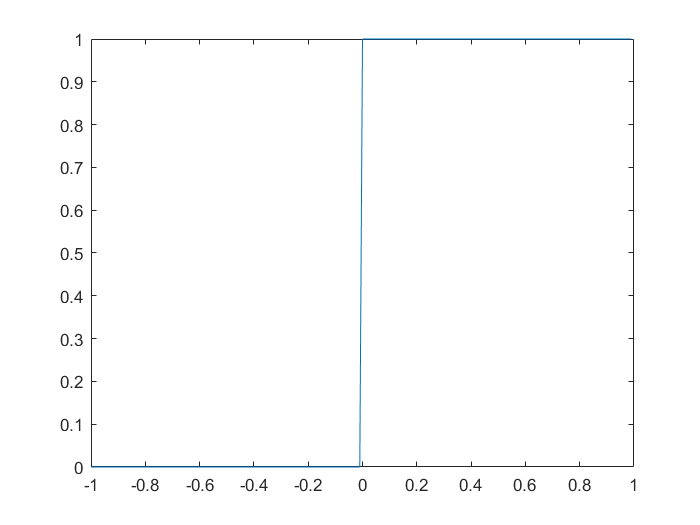

t = (-1:0.01:1-0.01);
unitstep = t>=0;
plot(t, unitstep)

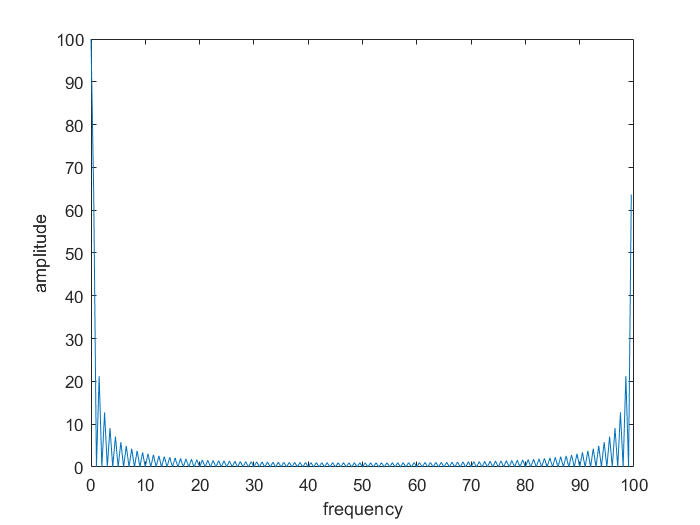

Y4 = fft(unitstep);

f4 = (0:length(Y4)-1)*Fs/length(Y4);
plot(f4,abs(Y4))
xlabel('frequency')
ylabel('amplitude')

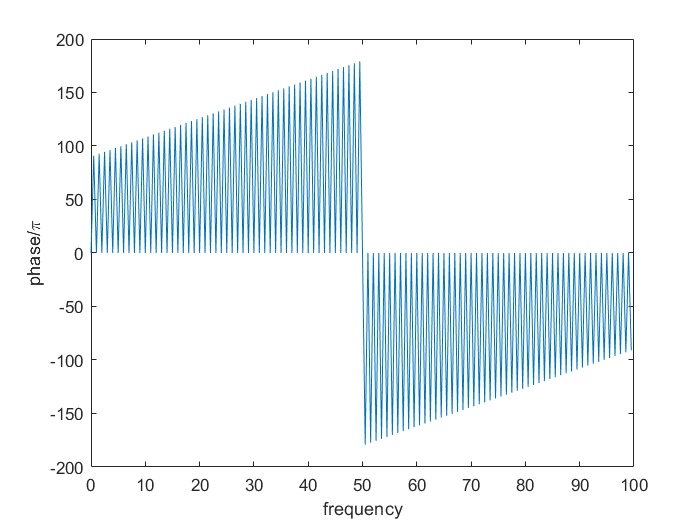


% Z4 = fftshift(Y4);
% f4 = (-length(Y4)/2:length(Y4)/2-1)*100/length(Y4);
tol = 1e-6;
Z4 = Y4;
Z4(abs(Z4)<tol)=0;
theta4 = angle(Z4);
plot(f4,theta4*180/pi)
xlabel('frequency')
ylabel('phase/\pi')

B3_3 An Impulse signal 

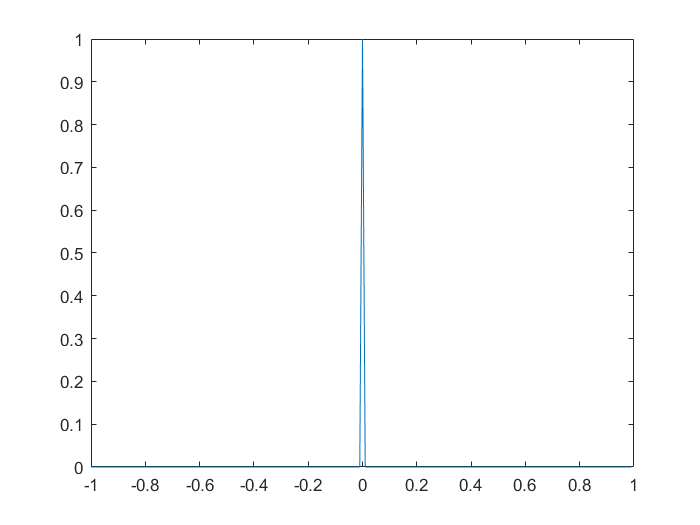

t = (-1:0.01:1-0.01);

impulse = t==0;
plot(t,impulse)

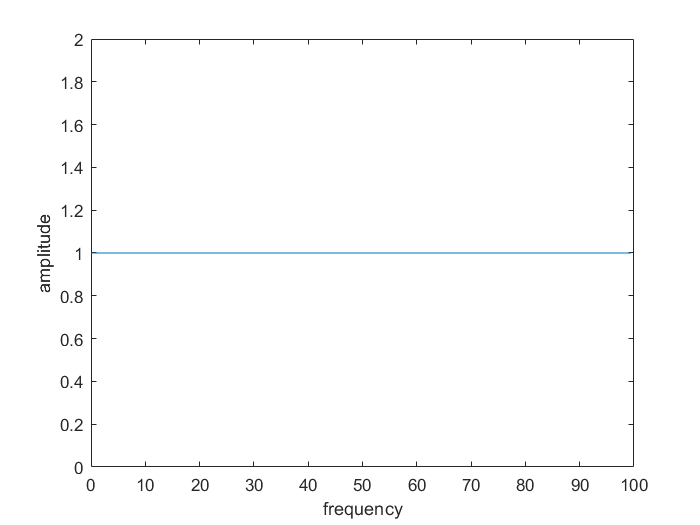

Y5 = fft(impulse);
f5 = (0:length(Y5)-1)*Fs/length(Y5);
plot(f5,abs(Y5))
xlabel('frequency')
ylabel('amplitude')

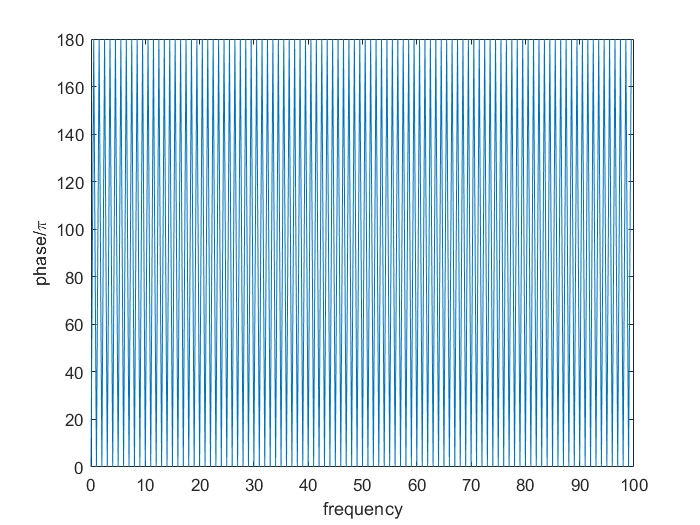


% Z5 = fftshift(Y5);
% f5 = (-length(Y5)/2:length(Y5)/2-1)*100/length(Y5);
% plot(f5,abs(Z5))
tol = 1e-6;
Z5 = Y5;
Z5(abs(Z5)<tol)=0;
theta5 = angle(Z5);
plot(f5,theta5*180/pi)
xlabel('frequency')
ylabel('phase/\pi')